digitDatasetPath ='C:\Users\Sean\Downloads\SideCam\scaled'

digitDatasetPath = 'C:\Users\Sean\Downloads\SideCam\scaled'

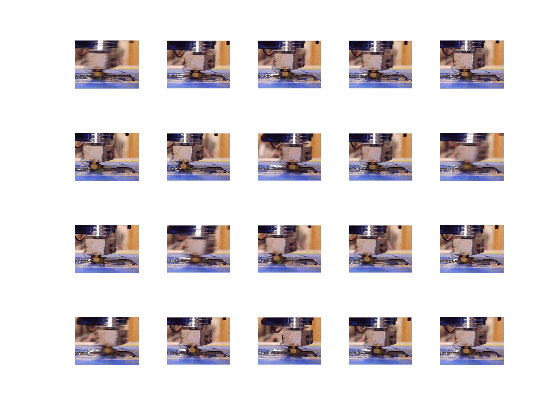

% fullfile(matlabroot,'toolbox','nnet','nndemos', ...
%    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
%fail: 842
%pass: 3254
%slide: 1124
figure;
perm = randperm(200,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end


labelCount = countEachLabel(imds)

labelCount = 3×2 table
    Label     Count
    ______    _____

    Fail0      223 
    Pass0      380 
    Slide0     338 


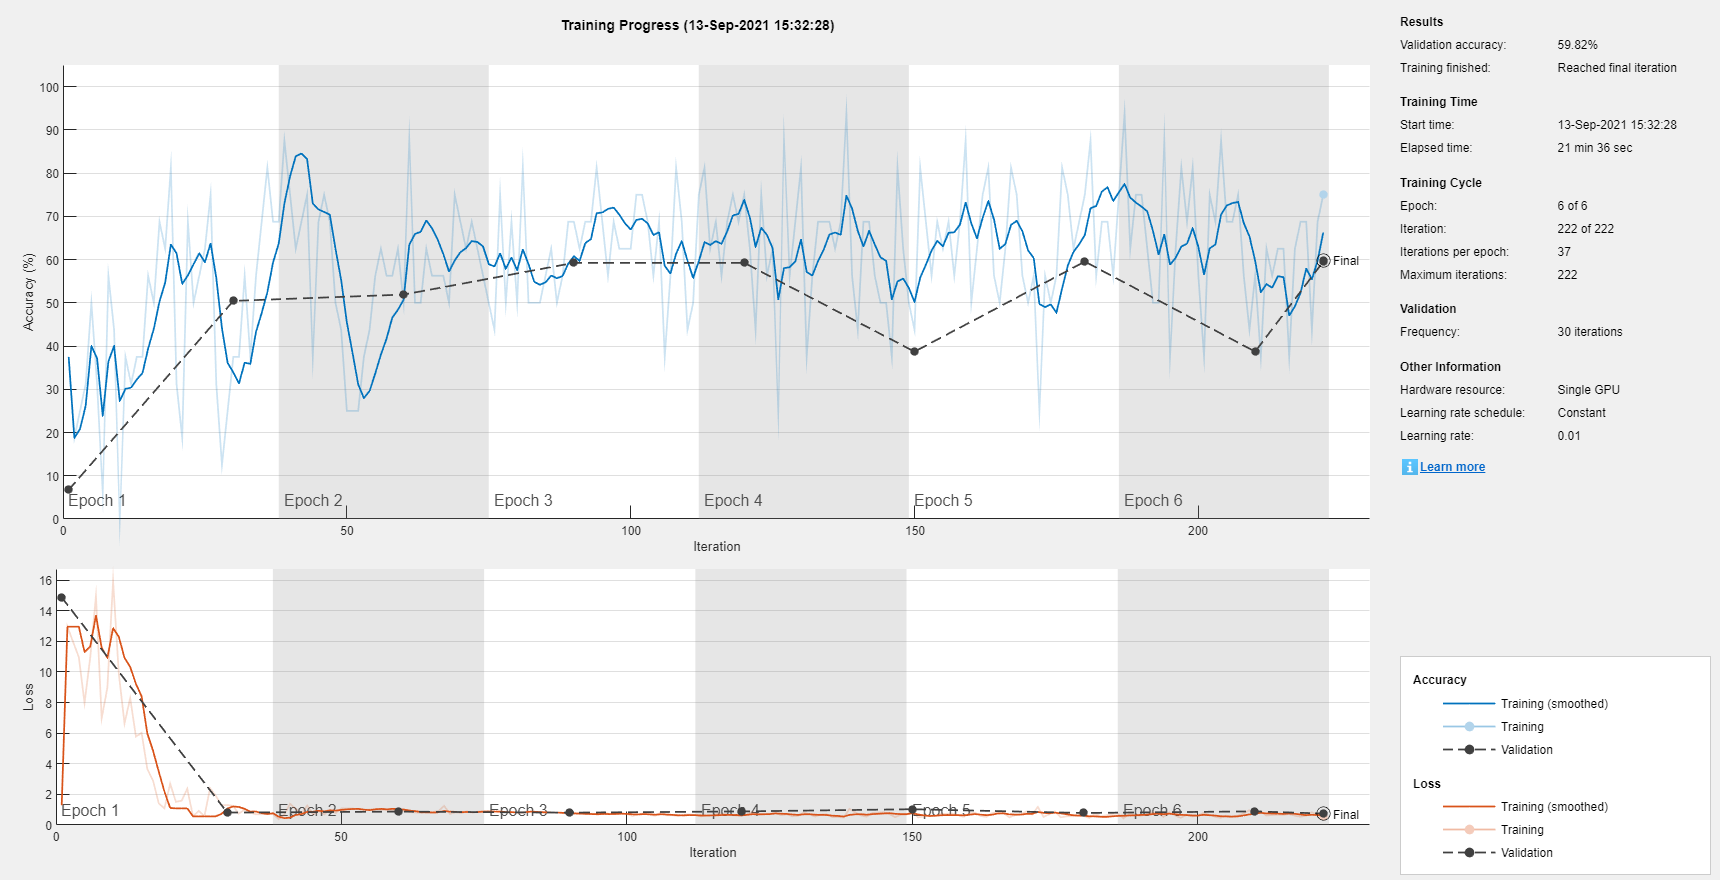



numTrainFiles = 200;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

layers = [
    imageInputLayer([1944/2 2592/2 3])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(3)
    softmaxLayer
    classificationLayer];


options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',6, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress','MiniBatchSize', 16);

net = trainNetwork(imdsTrain,layers,options);


analyzeNetwork(net)

YPred = classify(net,imdsValidation);

Error using DAGNetwork/classify (line 175)
Out of memory on device. To view more detail about available memory on the GPU, use 'gpuDevice()'. If the problem persists, reset the GPU by calling 'gpuDevice(1)'.

Error in SeriesNetwork/classify (line 528)
            [labels, scores] = this.UnderlyingDAGNetwork.classify(X, varargin{:});

YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)